# 新しいControllerクラスの定義

本ページでは新たな制御器モデルの定義方法について解説します。

まず初めに以下のコマンドを実行してください。

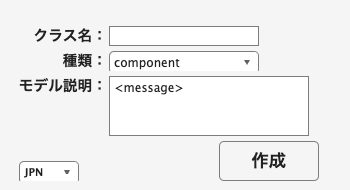

 
defineClass

実行するとUIが起動されます。

## **UI上での操作**

    それぞれの欄に適切に内容を入力します。

-     クラス名：設計する制御器を簡潔に表す名称を指定してください。ただし特殊文字を含まず、数字等から始まらない有効な文字列である必要があります。

-     種類：controllerを選択します。

-     モデル説明：設計する制御器に応じてモデルの概要を自由に記述してください。

    「作成」ボタンを押すと保存先のフォルダを選択する画面になるので希望のフォルダを選択してください。

    ただし、保存先のフォルダは現在のMATLABの検索パスに含まれている必要があります。

## **テンプレートファイルに設計したモデルを記述する**

    基本的にテンプレートファイルに記述されている通りに記入していただければ問題ありません。

    主に記述するべきメソッドは「obj.get_nx」と「obj.get_dx_u」の２つです。

####     obj.get_nx( )

        状態変数の個数を出力するメソッド

####     obj.get_dx_u( )

        動特性を定義するメソッド

        このメソッドを定義するためには接続するの動特性を把握している必要があります。

        controllerクラスには、以下の２つのプロパティがあります。

- obj.index_observe

- obj.index_input

        get_dx_uメソッドには、index_observeで指定した機器/母線の「状態・電圧・電流・グローバルコントローラからの入力」が番号ごとにcellで格納されています。

        例えば、index_observeで指定した機器の１番目がcomponent.generator.one_axis、２番目がcomponent.generator.load.powerであった場合

- `X{1}には[δ;ω;Eq]が、X{2}には[空行列]が格納`

- `V{1}には[Vre1; Vim1]が、V{2}には[Vre2; Vim2]が格納`

- `I{1}には[Ire1; Iim1]が、I{2}には[Ire2; Iim2]が格納`

- `u_global{1}には[Vfd1; Pm1]へ、u_global{2}には[Pload2; Qload2]へグローバルコントローラからの入力があればその値を観測できます`

        引数`x`には対象の制御器の内部状態が入力されてきます。

        一方で出力は、dxが制御器の内部状態の微分値と、各機器への入力値を指定します。

        出力`dx`は`double`型のベクトルで定義してください

        出力`u`は`cell`配列として定義します。`cell`内の各入力値は、`index_inputに対応した機器への入力値をdouble型のベクトルとして定義します。`

        先の例と同様に、index_observeで指定した機器の１番目がcomponent.generator.one_axis、２番目がcomponent.generator.load.powerであった場合

- `u{1}には[Vfd1; Pm1]への入力値を指定するため2x1の配列を、`

- `u{2}には[Pload2; Qload2]への入力値を指定するため同様に2x1の配列を格納しておく必要があります。`


function [dx, u] = get_dx_u(obj, t, x, X, V, I, u_global)
    % 引数：
    % t : 時刻を表すスカラー値。単位は秒（s)
    % x : 制御器の状態ベクトル
    % X : 観測対象の機器の状態。型は各機器の状態ベクトルのcell配列。
    % V : 観測対象の機器が接続する母線の電圧。２×[観測対象の母線の個数]のdouble型配列
    % I : 観測対象の機器が接続する母線の電圧。２×[観測対象の母線の個数]のdouble型配列
    % u_global : globalコントローラからの各機器への入力ベクトル

    % 出力：
    % dx : 制御器の状態の時間微分のベクトル
    % u  : 制御器の出力ベクトル（各機器への入力ごとのcell配列として定義）


    %%%%%%%%%% 実装 %%%%%%%%%%

    % 観測対象の機器の状態・入力および母線電圧/電流を取得
        x1 = X{1};
         :
        xi = X{i};

        V1 = V{1};
         :
        Vi = V{i};

        I1 = I{1};
         :
        Ii = I{i};

        u1 = u_global{1};
         :
        ui = u_global{i};


    % 状態の微分値と制御入力を定義
        dx =   ; %状態の微分値の配列数は、get_nxメソッドで定義した状態数と一致すること

        u1 = 
         :
        ui = 

    % 制御入力は機器ごとのcell配列に変換
        u  = {u1,...,ui}

    %%%%%%%%%%%%%%%%%%%%%%%%%

end
